# ======= PARTE 1 - MAS =======

% Setup e analisi  per un problema di aggregazione 
% Autore: [Marina Granozio 607259]

## ================================

clear all; close all; clc;

## ======== INIZIALIZZAZIONE ========

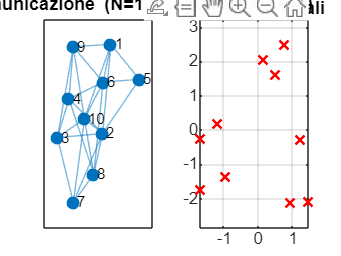

% Parametri
T = 0.05;       % Passo integrazione
tfin = 15;      % Tempo finale

% Potenziali
param.a = 0.5;  % Attrazione (lineare)
param.b = 5.0;  % Repulsione (esponenziale)
param.c = 0.5;  % Ampiezza repulsione

% Generazione Grafo
N = 10;         % Numero agenti
P = 0.6;        % Probabilità connessione (densità archi)
G_adj = MAS_Graph(N, P);
n_archi = sum(sum(triu(G_adj)));

% Posizioni Iniziali Casuali
x0 = 5 * (rand(N, 2) - 0.5); 

L_graph   = diag(sum(G_adj, 2)) - G_adj;        % Laplaciano
eig_vals  = sort(eig(L_graph));                 % Ordinamento autovalori
lambda_2  = eig_vals(2);                        % Secondo autovalore
m_edges   = nnz(triu(G_adj));                   % |E|

figure(1); tiledlayout(1,2);
nexttile;
Gobj = graph(G_adj);
p = plot(Gobj, 'Layout','force', 'NodeLabel', 1:N, 'MarkerSize', 6);
title(sprintf('Grafo di comunicazione (N=%d, |E|=%d, \\lambda_2=%.3f)', N, m_edges, lambda_2));

nexttile;
plot(x0(:,1), x0(:,2), 'rx', 'MarkerSize',7, 'LineWidth',1.2); % posizioni iniziali
title('Posizioni iniziali');
axis equal; grid on;

drawnow;

#### Aggregazione

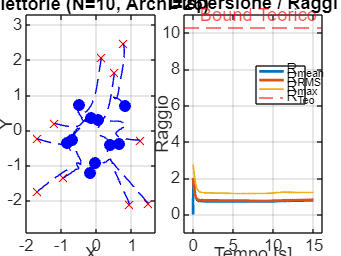

% Swarm senza guida
u_g = [0, 0]; 

% Ostacoli
obstacles = []; 

% Simulazione
[x_hist, t, disp_metric] = MAS_Swarm(G_adj, x0, T, tfin, u_g, param, obstacles);

% Raggio RMS e raggio massimo nel tempo
rms_radius = zeros(size(t));
rmax       = zeros(size(t));

for k = 1:numel(t)
    centroid_k = mean(x_hist(:,:,k), 1);
    d_k = vecnorm(x_hist(:,:,k) - centroid_k, 2, 2);  % Nx1
    rms_radius(k) = sqrt(mean(d_k.^2));
    rmax(k)       = max(d_k);
end

% Plot
figure(2); 
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

% Traiettorie 
axL = nexttile(1); hold(axL,'on'); grid(axL,'on'); axis(axL,'equal');
plot(axL, x0(:,1), x0(:,2), 'rx', 'DisplayName','Start');
title(axL, sprintf('Traiettorie (N=%d, Archi=%d)', N, n_archi), 'FontSize', 9);

for i=1:N
    plot(axL, squeeze(x_hist(i,1,:)), squeeze(x_hist(i,2,:)), 'b--');
    plot(axL, x_hist(i,1,end), x_hist(i,2,end), 'bo', 'MarkerFaceColor','b');
end

xlabel(axL,'X'); ylabel(axL,'Y');

% Dispersione e bound 
axR = nexttile(2); hold(axR,'on'); grid(axR,'on');
plot(t, disp_metric, 'LineWidth', 1.5, 'DisplayName','R_{mean}');
plot(t, rms_radius,  'LineWidth', 1.5, 'DisplayName','R_{RMS}');
plot(t, rmax,        'LineWidth', 1.0, 'DisplayName','R_{max}');
title('Dispersione / Raggi','FontSize',8);
xlabel('Tempo [s]'); ylabel('Raggio');

% Bound Teorico
L_graph = diag(sum(G_adj, 2)) - G_adj; % Laplaciano
autovalori = sort(eig(L_graph));       % Ordinamento crescente autovalori
lambda_2 = autovalori(2);              % Secondo autovalore

if lambda_2 > 1e-5
    th_val = sqrt(param.b * n_archi / (param.a * lambda_2));
    yline(axR, th_val, 'r--', 'Bound Teorico','DisplayName','R_{Teo}');
    ylim([0, max([th_val * 1.3, rmax(end)*1.3,1])]); 
end

ZOOM_ON = true; 
if ZOOM_ON
    xlim(axR, [0 5]);    
    ylim(axR, [0 15]);   
end

axis(axL, 'padded'); axis(axR, 'padded');
set([axL axR], 'Box','on','FontSize',9);

nexttile(2)
legend(["R_{mean}", "R_{RMS}", "R_{max}", "R_{Teo}"], "Position", [0.7529 0.5963 0.1436, 0.1467])

drawnow;

## ====== ANALISI PRESTAZIONI ======

#### Analisi di sensibilità dei parametri (Attrazione vs Repulsione)

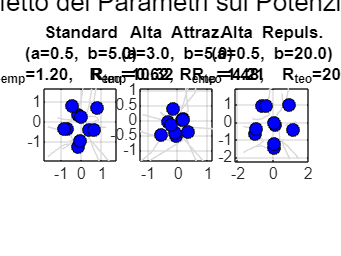

scenarios = {
    'Standard',     0.5,  5.0;
    'Alta Attraz.', 3.0,  5.0;
    'Alta Repuls.', 0.5, 20.0
};
tfin_sens = 20;

% Plot
figure(3); clf; set(gcf,'Color','w');
sgtitle('Effetto dei Parametri sui Potenziali','Fontsize',14);

% Laplaciano e λ2
L_tmp     = diag(sum(G_adj,2)) - G_adj;
eigen_tmp = sort(eig(L_tmp));
lam2      = eigen_tmp(2);

for k = 1:3
    curr_title  = scenarios{k,1};
    param_var   = param;
    param_var.a = scenarios{k,2};
    param_var.b = scenarios{k,3};

    [x_var, ~, ~] = MAS_Swarm(G_adj, x0, T, tfin_sens, u_g, param_var, []);

    ax = subplot(1,3,k); hold(ax,'on'); grid(ax,'on'); axis(ax,'equal');
    box(ax,'on');

    % Traiettorie
    for i=1:N
        plot(ax, squeeze(x_var(i,1,:)), squeeze(x_var(i,2,:)), ...
             'Color', [0.85 0.85 0.85], 'LineWidth', 0.8);
    end

    scatter(ax, x_var(:,1,end), x_var(:,2,end), 48, 'b', 'filled', 'MarkerEdgeColor','k');

    % Baricentro e raggi
    centroide = mean(x_var(:,:,end),1);
    d_final   = vecnorm(x_var(:,:,end) - centroide, 2, 2);
    R_emp     = max(d_final);  

    % Bound teorico
    R_teo = sqrt((param_var.b * n_archi) / (param_var.a * lam2));

    % Cerchio del bound
    th = linspace(0,2*pi,240);
    plot(ax, centroide(1)+R_teo*cos(th), centroide(2)+R_teo*sin(th), 'r--', 'LineWidth', 1.2);
   
    margin = max(0.4*R_emp, 0.6);
    xlim(ax, [centroide(1)-(R_emp+margin), centroide(1)+(R_emp+margin)]);
    ylim(ax, [centroide(2)-(R_emp+margin), centroide(2)+(R_emp+margin)]);

    title(ax, {curr_title, ...
               sprintf('(a=%.1f, b=%.1f)', param_var.a, param_var.b), ...
               sprintf('R_{emp}=%.2f,  R_{teo}=%.2f', R_emp, R_teo)}, ...
          'FontSize', 9, 'Interpreter','tex');
end

drawnow;

#### Analisi input di guida (u_g)

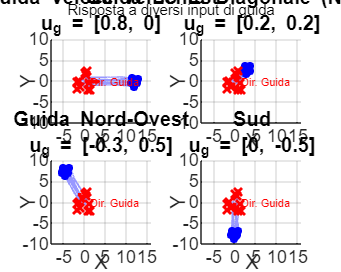

% Scenari di guida 
ug_list = {
    [0.8, 0],     'Guida Veloce verso Est';
    [0.2, 0.2],   'Guida Lenta Diagonale (Nord-Est)';
    [-0.3, 0.5],  'Guida Nord-Ovest';
    [0, -0.5],       'Sud'
};

figure(4); set(gcf, 'Color', 'w','Position', [100, 100, 1000, 800]);
sgtitle('Risposta a diversi input di guida','FontSize', 11);

for k = 1:4
    curr_ug = ug_list{k, 1};
    curr_title = ug_list{k, 2};
    
    % Simulazione
    [x_guide, ~, ~] = MAS_Swarm(G_adj, x0, T, tfin, curr_ug, param, []);
    
    % Plot
    subplot(2, 2, k); hold on; grid on; axis equal;
    title({curr_title; ['u_g = [' num2str(curr_ug(1)) ', ' num2str(curr_ug(2)) ']']});
   
    % Traiettorie
    for i=1:N
        plot(squeeze(x_guide(i,1,:)), squeeze(x_guide(i,2,:)), 'Color', [0.6 0.6 1]); 
    end
   
    % Posizioni Finali
    for i=1:N        
    plot(x_guide(i,1,end), x_guide(i,2,end), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 4);
    end

    % Posizione Iniziale
    plot(x0(:,1), x0(:,2), 'rx', 'LineWidth', 1.5);

    % Direzione della guida dal centroide iniziale
    if norm(curr_ug) > 0
        c_start = mean(x0, 1);
        quiver(c_start(1), c_start(2), curr_ug(1)*4, curr_ug(2)*4,'r', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');
        text(c_start(1), c_start(2), '  Dir. Guida', 'Color', 'r', 'FontSize', 6);
    end
    
    xlabel('X'); ylabel('Y');
    
    xlim([-8 16]); 
    ylim([-10 10]);
end

drawnow;

#### Effetto di N e P

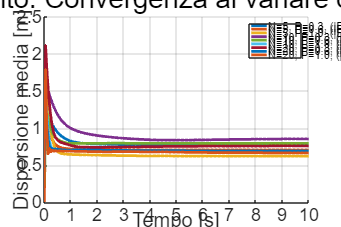

N_test = [5, 10, 20];     % Nodi
P_test = [0.3, 0.6, 1.0]; % Densità archi
results = [];             % [N, P, |E|, lambda2, Disp_end, Tconv]

figure(5); hold on; grid on;
set(gcf, 'Position', [100, 100, 900, 600], 'Color', 'w');
sgtitle('Confronto: Convergenza al variare di N e P');
xlabel('Tempo [s]'); ylabel('Dispersione media [m]');
colors = lines(length(N_test)*length(P_test));

cnt = 0;
legend_test = {};

for n = N_test
    for p = P_test
        cnt = cnt + 1;
        
        % Generazione grafo e condizioni
        G_tmp = MAS_Graph(n, p);
        x0_tmp = 5 * (rand(n, 2) - 0.5);        
        m_edges = nnz(triu(G_tmp));       % Numero archi
        is_rigid = m_edges >= (2*n - 3);  % Rigidità

        % Calcolo Lambda2        
        L_tmp = diag(sum(G_tmp,2)) - G_tmp;
        eigen = sort(eig(L_tmp));
        if length(eigen) >= 2
            lam2 = eigen(2); 
        else 
            lam2=0; 
        end

        % Simulazione
        [~, t_tmp, m_size] = MAS_Swarm(G_tmp, x0_tmp, T, 10, [0 0], param, []);

        n_samples = length(m_size);
        val_steady = mean(m_size(round(n_samples*0.9):end));

        upper_b = val_steady * 1.05;
        lower_b = val_steady * 0.95;
               
        is_outside = (m_size > upper_b) | (m_size < lower_b);
        idx_last = find(is_outside, 1, 'last');
        
        if isempty(idx_last)
            Tconv = 0;
        else            
            idx_conv = min(n_samples, idx_last + 1);
            Tconv = t_tmp(idx_conv);
        end
        
        % Plot
        plot(t_tmp, m_size, 'Color', colors(cnt,:),'LineWidth', 1.5)
        legend_test{cnt} = sprintf('N=%d, P=%.1f, (|E|=%d)',n, p, m_edges);        
        
        results = [results; n, p, m_edges, lam2, val_steady, Tconv, is_rigid];
    end
end
legend(legend_test,'Location','best','FontSize', 6);

Tperf = array2table(results, 'VariableNames', {'N','P','NumEdges','lambda2','FinalDispersion','Tconv[s]','Rigidity'});
disp(Tperf)

    N      P     NumEdges     lambda2      FinalDispersion    Tconv[s]    Rigidity
    __    ___    ________    __________    _______________    ________    ________

     5    0.3        3       5.0451e-17        0.78014          1.05         0    
     5    0.6        8                3        0.70564           0.6         1    
     5      1       10                5        0.61957          0.75         1    
    10    0.3       11          0.29491        0.85303           2.1         0    
    10    0.6       22            1.471        0.79124           0.6         1    
    10      1       45               10        0.68447           0.3         1    
    20    0.3       63           2.5307        0.75822          0.75         1    
    20    0.6 

drawnow;

#### Robustezza - Rimozione archi e verifica consenso

N_rob = 10;         
G_rob = MAS_Graph(N_rob, P); 
x0_rob = 5 * (rand(N_rob, 2) - 0.5);

degrees = sum(G_rob, 2);                     % Grado di ogni nodo
[min_deg, weak_node] = min(degrees);         % Trova il nodo critico
fprintf('Il nodo più debole è il %d (con %d archi).\n', weak_node, min_deg);

Il nodo più debole è il 8 (con 2 archi).


G_broken = G_rob;
neighbours = find(G_rob(weak_node, :) == 1); % Trova i vicini del nodo critico

% Rimozione Archi
for v = neighbours
    G_broken(weak_node, v) = 0;
    G_broken(v, weak_node) = 0;
end

% Verifica Disconnessione
L_broken = diag(sum(G_broken,2)) - G_broken;
ee = sort(eig(L_broken));
lam2_broken = ee(2);

if lam2_broken < 1e-5
    status = sprintf('Disconnessione (nodo %d isolato )', weak_node);
    fprintf('Grafo spezzato rimuovendo %d archi.\n', min_deg);
else
    status = 'Ancora Connesso';
end

Grafo spezzato rimuovendo 2 archi.


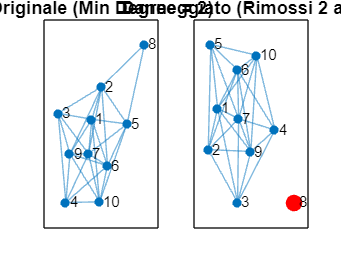

% Simulazione con guida 
[x_rob, ~, ~] = MAS_Swarm(G_broken, x0_rob, T, tfin, [0.5, 0], param, []);

% Plot (Grafo Originale vs "Rotto")
figure(6); set(gcf, 'Color', 'w');

subplot(1,2,1); 
plot(graph(G_rob), 'NodeLabel', 1:N_rob, 'Layout', 'force'); 
title(['Originale (Min Degree = ' num2str(min_deg) ')']);

subplot(1,2,2); 
h = plot(graph(G_broken), 'NodeLabel', 1:N_rob, 'Layout', 'force');
highlight(h, weak_node, 'NodeColor', 'r', 'MarkerSize', 8);
title(['Danneggiato (Rimossi ' num2str(min_deg) ' archi)']);

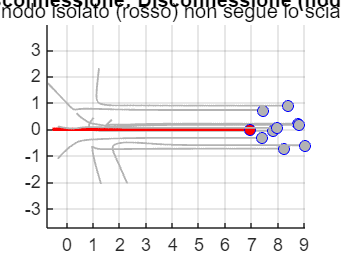

figure(7); hold on; grid on; axis equal;
title(['Effetto Disconnessione: ' status]);
subtitle('Il nodo isolato (rosso) non segue lo sciame');

% Traiettorie
for i=1:N_rob
    if i == weak_node
        col = 'r'; lw = 2.0; 
    else
        col = [0.7 0.7 0.7]; lw = 1.0;
    end
    plot(squeeze(x_rob(i,1,:)), squeeze(x_rob(i,2,:)), 'Color', col, 'LineWidth', lw);
    plot(x_rob(i,1,end), x_rob(i,2,end), 'bo', 'MarkerFaceColor', col);
end

drawnow;

## ===== COLLISION AVOIDANCE =====

xL = -0.5; xR = 1.5;
yvals  = linspace(-3,3,5)';
obs_pos = [xL*ones(numel(yvals),1), yvals;  xR*ones(numel(yvals),1), yvals];

% Parametri
param.obs_range = 1.5;   % Raggio dischi
param.k_obs     = 4.0;   % Repulsione ostacoli

% Guida che forza lo sciame ad attraversarli
u_g_obs = [0.5, 0];

% Simulazione
[x_obs, t_obs, ~] = MAS_Swarm(G_adj, x0, T, tfin, u_g_obs, param, obs_pos);

% Plot
figure(8);  hold on; grid on; axis equal; title('Collision Avoidance');
th = linspace(0,2*pi,180);

for j = 1:size(obs_pos,1)
    plot(obs_pos(j,1)+param.obs_range*cos(th), obs_pos(j,2)+param.obs_range*sin(th), 'r-', 'LineWidth', 1.2);
end
plot(obs_pos(:,1), obs_pos(:,2), 'o', 'MarkerFaceColor','r','MarkerEdgeColor','k','MarkerSize',8);

for i = 1:N
    plot(squeeze(x_obs(i,1,:)), squeeze(x_obs(i,2,:)), 'k-', 'LineWidth', 1.0);
end
xlabel('X [m]'); ylabel('Y [m]'); 
axis padded; 
drawnow;

#### Analisi collision avoidance: clearance e violazioni

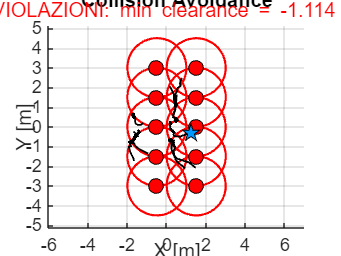

Nt  = size(x_obs,3);
clr = inf(N, Nt);
R   = param.obs_range;

for k = 1:Nt
    for i = 1:N
        d = vecnorm(obs_pos - x_obs(i,:,k), 2, 2);
        clr(i,k) = min(d) - R;
    end
end

[min_agent_clr,~] = min(clr,[],2);
[glob_min, idx_i] = min(min_agent_clr);
[~, kstar]        = min(clr(idx_i,:));
plot(x_obs(idx_i,1,kstar), x_obs(idx_i,2,kstar), 'p', 'MarkerFaceColor',[0 0.6 1], 'MarkerEdgeColor','k', 'MarkerSize',10);

any_violation = (glob_min < 0);
subtitle(sprintf('%s min clearance = %.3f m', ternary(any_violation,'\color{red}VIOLAZIONI:','\color{green}OK:'), glob_min));

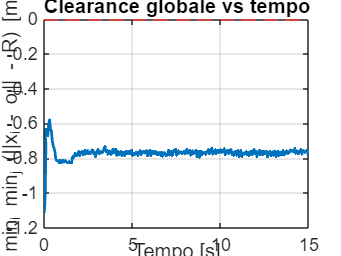


% Clearance globale
figure(9); set(gcf,'Color','w');
plot(t_obs, min(clr,[],1), 'LineWidth',1.5); grid on;
yline(0,'r--','Unsafe');
xlabel('Tempo [s]'); ylabel('min_i min_j (||x_i - o_j|| - R) [m]');
title('Clearance globale vs tempo'); drawnow;

status_str = 'OK';
if any_violation, 
    status_str = 'VIOLATION'; 
end
fprintf('Collision avoidance: min_clearance_global = %.3f m  (%s)\n', glob_min, status_str);

Collision avoidance: min_clearance_global = -1.114 m  (VIOLATION)


function s = ternary(cond,a,b)
    if cond
        s=a; 
    else s=b; 
    end
end